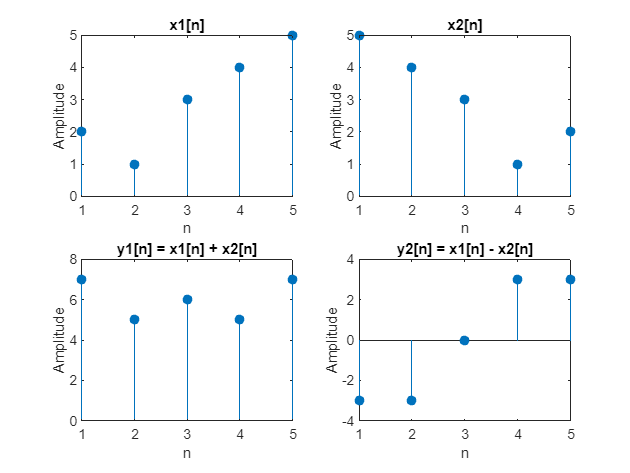

% Define the signals x1[n] and x2[n]
x1 = [2, 1, 3, 4, 5];
x2 = [5, 4, 3, 1, 2];

% Generate y1[n] = x1[n] + x2[n]
y1 = lincomp_RollNO(1, 1, x1, x2);

% Generate y2[n] = x1[n] - x2[n]
y2 = lincomp_RollNO(1, -1, x1, x2);

% Plot x1[n] and x2[n]
subplot(2, 2, 1);
stem(x1, 'filled');
title('x1[n]');
xlabel('n');
ylabel('Amplitude');

subplot(2, 2, 2);
stem(x2, 'filled');
title('x2[n]');
xlabel('n');
ylabel('Amplitude');

% Plot y1[n] and y2[n]
subplot(2, 2, 3);
stem(y1, 'filled');
title('y1[n] = x1[n] + x2[n]');
xlabel('n');
ylabel('Amplitude');

subplot(2, 2, 4);
stem(y2, 'filled');
title('y2[n] = x1[n] - x2[n]');
xlabel('n');
ylabel('Amplitude');

function x3 = lincomp_RollNO(a, b, x1, x2)
    % Linear combination of two signals
    x3 = a .* x1 + b .* x2;
end
